%LAb Final

%Especificaciones
%C1= ep= 0; ts<1s ;mp=15%

%G=(2.027)/((0.0546*s^2)+(0.8225*s)+1)  %JHon parra %R=10k


%G=2.024/(0.02592*s^2+0.7834*s+1) JAIR NAVARRO
%P=[-15+15i -15-15i -75]

%G=2.026/(0.03967*s^2+0.7961*s+1) % juan
%polos deseados [-10.04-10.04i -10.04+10.04i -50.18]

s=tf('s');
%G=(2)/((0.1*s+1)*(0.25*s+1))
Gi=(132.16)/((s+4.027)*(s+16.07))

Ge=ss(G) %Para hallar la matriz de espacio de estados
A=Ge.a; B=Ge.b;C=Ge.c;D=Ge.d; %Separamos nuestras matrices
order(G)
Mc=rank(ctrb(A,B))

ts=1 %Ts deseado
mp=0.15; %Mp deseado
zeta=-log(mp)/(sqrt(pi^2+log(mp)^2))
wn=4/(zeta*ts) %% criterio del 2%
sigma=zeta*wn
wd=wn*sqrt(1-zeta^2)
sx=-sigma+wd*i %%polos deseados

P=[sx sx']'
Pa=[P; -87]%Ponemos un polo extra que quede bastante lejos, se ubica manualmente

%Pa=[-7.45+7.45i -7.45-7.45i -37.27]  %polos jhon

Pob=P(1:2)*10

L=acker(A',C',Pob)'

Aa=[Ge.a,[0;0];-Ge.c,0]
Ba=[Ge.b;0]
Ca= [Ge.c 0]

Ka=place(Aa,Ba,Pa);     %Hallamos los valores de k
K=Ka(1:end-1)           %Valores de k
ki=-Ka(end)             %Valor de k para integrador

%Validacion
Ge_ci= ss(Ge.A-Ge.B*K,Ge.B,Ge.C,0);
Ge_ci=tf(Ge_ci)
Tci=feedback(Ge_ci*ki/s,1);
figure();
step(Tci),legend
stepinfo(Tci)



%C2 Ep=0; -5+5i -5-5i -10
s=tf('s');
%G=(2)/((0.1*s+1)*(0.25*s+1)) %ideal
Gi=(132.16)/((s+4.027)*(s+16.07)) %real

Ge=ss(Gi) %Para hallar la matriz de espacio de estados
A=Ge.a; B=Ge.b;C=Ge.c;D=Ge.d; %Separamos nuestras matrices
order(Gi)
Mc=rank(ctrb(A,B))

Pa=[-5+5i -5-5i -10]

Aa=[Ge.a,[0;0];-Ge.c,0]
Ba=[Ge.b;0]
Ca= [Ge.c 0]

Pob=Pa(1:2)*10

L=acker(A',C',Pob)'


Ka=place(Aa,Ba,Pa);     %Hallamos los valores de k
K=Ka(1:end-1)           %Valores de k
ki=-Ka(end)             %Valor de k para integrador
%Validacion
Ge_ci= ss(Ge.A-Ge.B*K,Ge.B,Ge.C,0);
Ge_ci=tf(Ge_ci)
Tci=feedback(Ge_ci*ki/s,1);
figure();
step(Tci),legend
stepinfo(Tci)
pole(Tci)








Gi=(132.16)/((s+4.027)*(s+16.07))

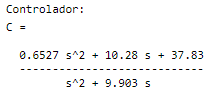

C1=((0.6527*s^2) + (10.28*s) + 37.83)/( s^2 + (9.903*s)) %Compensador para planta real

%C3 -5+5i -5-5i -10 -10  ; seguimiento a referencia ep=0
C=((43*s^2)+(680*s)+2500)/((40*s^2)+(640*s)) %ideal